# Standard Operating Policy

## Define model params

params.nat.S = 211500000;
params.nat.beta = 86.6021881286577;
params.nat.alpha = 1.95062290363465;
params.nat.h0 = -1.27;

params.reg.w = 100;
params.reg.hmin = 0;
params.reg.hmax = 1.5;

params.reg.h1 = 0.3;
params.reg.h2 = 1.0;

params.reg.m1 = 300;
params.reg.m2 = 1000;

h = -2:0.01:2;
N = zeros(size(h));
idx = find(h>params.nat.h0);
N(idx) = params.nat.beta*(h(idx) - params.nat.h0).^params.nat.alpha;

### Regulated release function

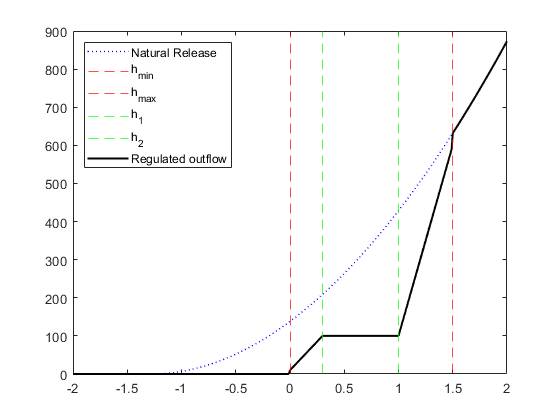

r = getRegulatedRelease(h, params);

figure;
plot(h, N, ':b','LineWidth',1)
hold on;
xline(params.reg.hmin,'--r');
xline(params.reg.hmax,'--r');

xline(params.reg.h1,'--g');
xline(params.reg.h2,'--g');

plot(h, r,'k','LineWidth',1.5)

legend('Natural Release', 'h_{min}', 'h_{max}', 'h_1', 'h_2','Regulated outflow','Location','northwest')

### Trajectories on real dynamics

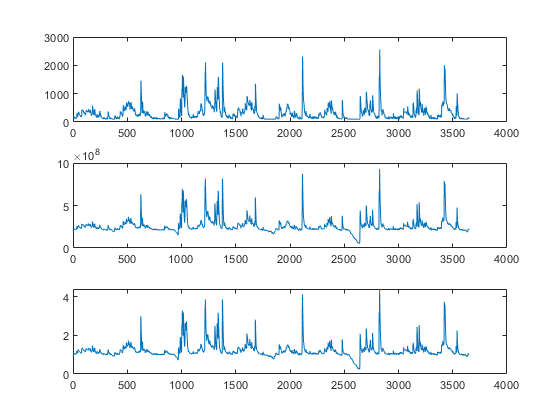

data = load("data\Verbano_inflows_74_83_nb.txt");
h_init = 0.88;

[r, s, h] = simLake(h_init, data, params);

figure; 
subplot(3,1,1); plot(r);
subplot(3,1,2); plot(s);
subplot(3,1,3); plot(h);

getVulnerability2(r,w,2)

ans = 0.3590

%     TODO: Params for lake Verbano
params2.p3 = 0.081;
params2.p2 = -0.483;
params2.p1 = 1.506;
params2.p0 = -1.578;
S = getFlooding2(h, 1.73, params2);
mean(S)

ans = 0.0286